Part 2

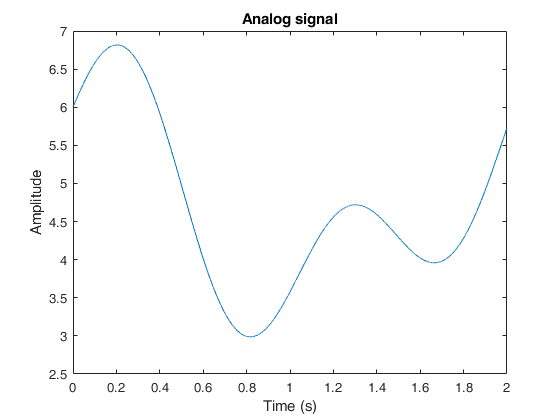

t = linspace(0,2,15000);
g = 4+sin(2*pi*t)+cos(pi*t)+cos(pi*t/2)+tan(pi*t/6);
plot(t,g)
xlabel("Time (s)")
ylabel("Amplitude")
title("Analog signal")

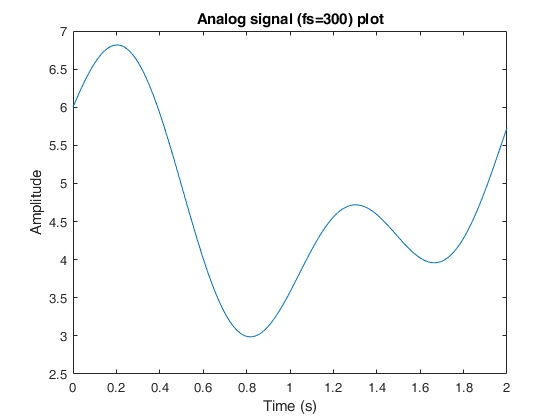

fs = 300;
t2 = 0:1/fs:2;
g_sample = 4+sin(2*pi*t2)+cos(pi*t2)+cos(pi*t2/2)+tan(pi*t2/6);
plot(t2,g_sample)
xlabel("Time (s)")
ylabel("Amplitude")
title("Analog signal (fs=300) plot")

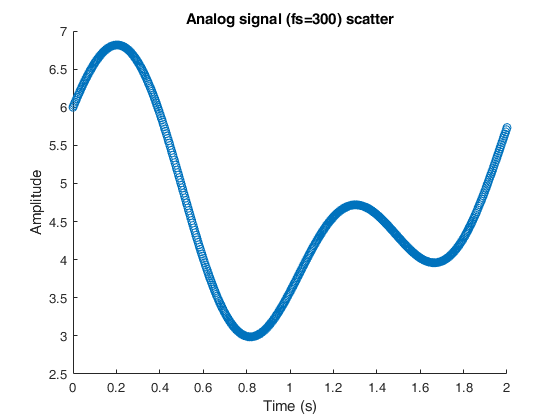

scatter(t2,g_sample)
xlabel("Time (s)")
ylabel("Amplitude")
title("Analog signal (fs=300) scatter")

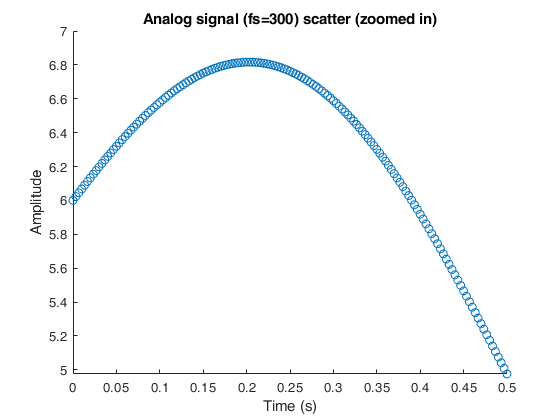

scatter(t2,g_sample)
xlabel("Time (s)")
ylabel("Amplitude")
title("Analog signal (fs=300) scatter (zoomed in)")
xlim([0 0.5])

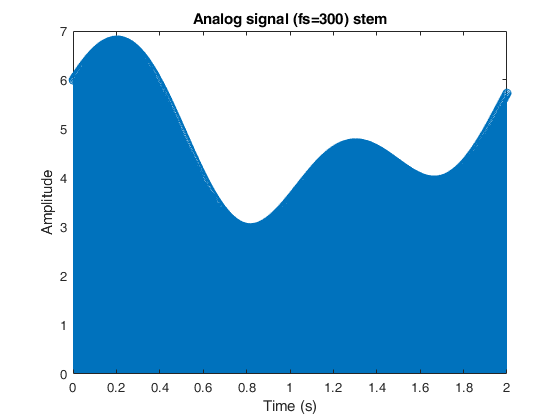

stem(t2,g_sample)
xlabel("Time (s)")
ylabel("Amplitude")
title("Analog signal (fs=300) stem")

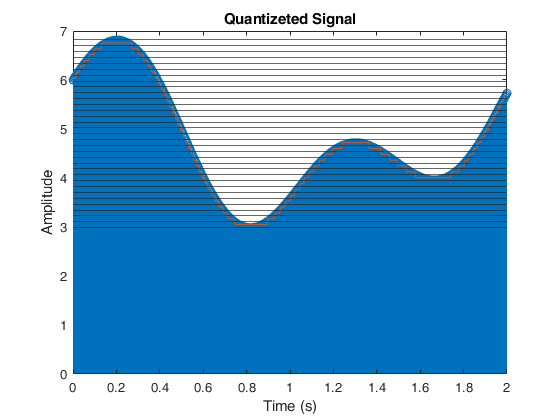

N = 33;
lines = linspace(min(g_sample),max(g_sample),N);
Quantization = zeros(1,length(g_sample));
hold on
for k=1:length(lines)
    yline(lines(k));
end
for i=1:length(Quantization)
    for j=1:length(lines)-1
        mean_two_line = (lines(j+1)+lines(j))/2;
        if(g_sample(i) >= lines(j) && g_sample(i) <= lines(j+1))
            Quantization(i) = mean_two_line;
        end
    end
end
plot(t2,Quantization)
xlabel("Time (s)")
ylabel("Amplitude")
title("Quantizeted Signal")
hold off

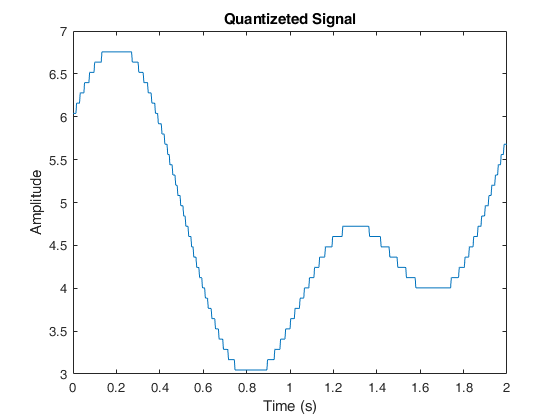

plot(t2,Quantization)
xlabel("Time (s)")
ylabel("Amplitude")
title("Quantizeted Signal")

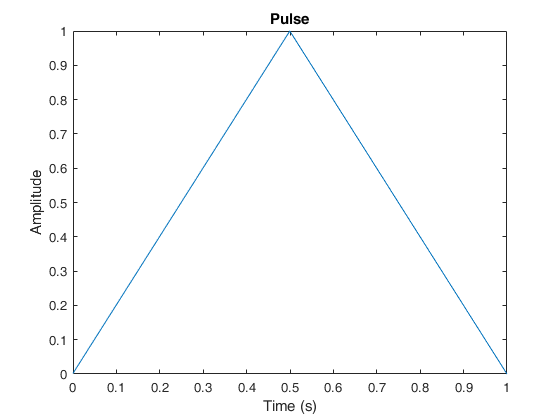

pulse = zeros(1,1000);
for i=1:length(pulse)
    if (i<=500)
        pulse(i)=2*i/1000;
    else
       pulse(i)=-(2)*(i/1000-1);
    end
end
t=linspace(0,1,length(pulse));
plot(t,pulse)
xlabel("Time (s)")
ylabel("Amplitude")
title("Pulse")

energy_pulse = 0;
for i=1:length(pulse)
    energy_pulse = energy_pulse + (pulse(i) * pulse(i));
end
energy_pulse

energy_pulse = 333.3340

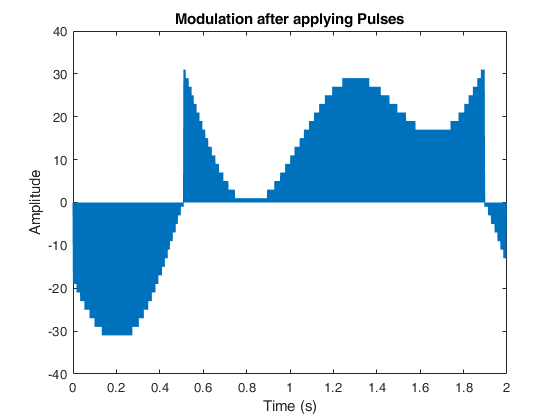

bits=zeros(1,length(Quantization));
for i = 1:length(Quantization)
    for j=1:32
        if (lines(j) <= Quantization(i) && Quantization(i) <= lines(j + 1))
            bits(i)=j - 1;
        end
    end
end
pulses = [1 3 5 7 9 11 13 15 17 19 21 23 25 27 29 31 -1 -3 -5 -7 -9 -11 -13 -15 -17 -19 -21 -23 -25 -27 -29 -31];
TwoD_array = [pulses;lines(1:N-1)];
modulate_signal = zeros(1,601000);
for i=1:length(bits)-1
    for j=1:32
        if (bits(i) == j - 1)
            modulate_signal((i-1)*1000 +1:i*1000) = pulses(j).*pulse;
        end
    end
end
t_s = linspace(0,2,length(modulate_signal));
plot(t_s,modulate_signal)
xlabel("Time (s)")
ylabel("Amplitude")
title("Modulation after applying Pulses")

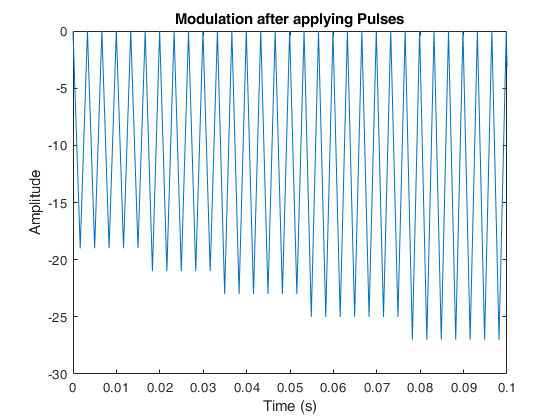

plot(t_s,modulate_signal)
xlim([0 0.1])
xlabel("Time (s)")
ylabel("Amplitude")
title("Modulation after applying Pulses")

energy_signal = 0;
for i=1:length(g)
    energy_signal = energy_signal + (g(i)*g(i));
end
energy_signal

energy_signal = 3.4497e+05

noise = randn(1,length(modulate_signal));
energy_noise = 0;
for i=1:length(g)
    energy_noise = energy_noise + (noise(i)*noise(i));
end
energy_noise

energy_noise = 1.4646e+04

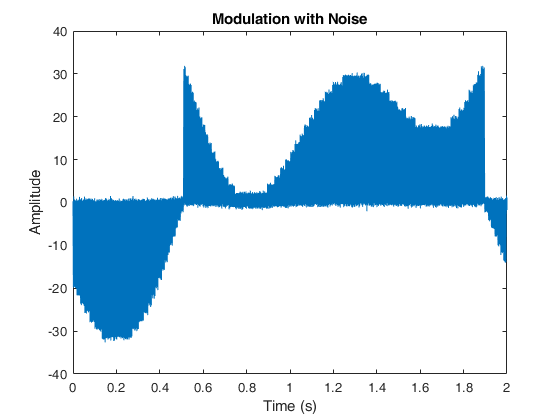

noise = normrnd(0,0.48,[1,length(modulate_signal)]);
signal_with_noise = modulate_signal + noise;
plot(t_s,signal_with_noise)
xlabel("Time (s)")
ylabel("Amplitude")
title("Modulation with Noise")

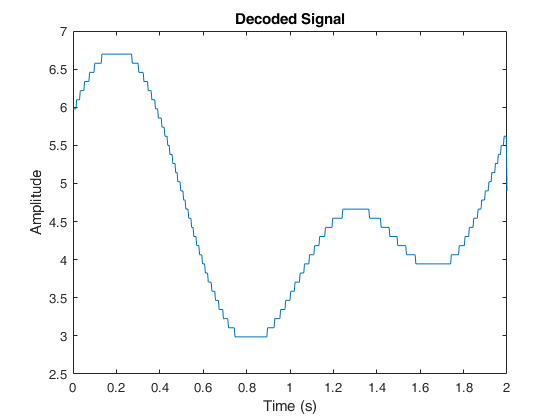

noise_pulse = zeros(1,length(pulse));
energy_each_pulse = zeros(1,length(bits));
for i=1:length(bits)
    noise_pulse = signal_with_noise(((i-1)*1000)+1:i*1000).*pulse;
    energy_each_pulse(i) = sum(noise_pulse) / energy_pulse;
end
decode_signal = zeros(1,length(energy_each_pulse));
for i=1:length(energy_each_pulse)
    nearest_odd_number = energy_each_pulse(i);
    is_odd = mod(nearest_odd_number,2) < 1;
    nearest_odd_number = floor(nearest_odd_number);
    nearest_odd_number(is_odd) = nearest_odd_number(is_odd)+1;
    energy_each_pulse(i) = nearest_odd_number;
    for j=1:length(lines)-1
        if (energy_each_pulse(i) == TwoD_array(1,j))
            decode_signal(i) = TwoD_array(2,j);
        end
    end
end
t_decode = linspace(0,2,length(decode_signal));
plot(t_decode,decode_signal)
xlabel("Time (s)")
ylabel("Amplitude")
title("Decoded Signal")